clear all;

T1 = 0.6;
T2 = 0.9;

T = T1 / 2;

d1 = exp(-T / T1)

d1 = 0.6065

d2 = exp(-T / T2)

d2 = 0.7165

a1 = -d1 -d2

a1 = -1.3231

a0 = d1 * d2

a0 = 0.4346


q0 = 10

q0 = 10

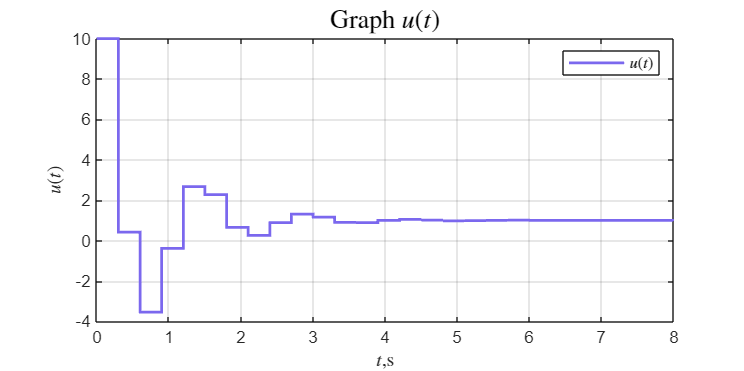



%======================================================
% GRAPHICS
%======================================================

set_param('schem_1/y', 'VariableName', 'y');
set_param('schem_1/u', 'VariableName', 'u');

out = sim('schem_1');
y_data = out.y.Data;
t_time = out.y.Time;
u_data = out.u.Data;
tu_data = out.u.Time;


% Построение графика

% Определяем цвета для линий
a_color = '#00FFFF'; 
b_color = '#7B68EE';
c_color = '#800080'; 
d_color = '#0000CD';
e_color = '#EE82EE';

figure('Position', [100 100 800 400]);
stairs(tu_data, u_data, '-', 'LineWidth', 1.5, 'Color', b_color);


grid on;

title('Graph $u(t)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$u(t)$','Interpreter', 'latex' );
xlabel('$t$,s', 'Interpreter', 'latex');
legend('$u(t)$','Interpreter', 'latex')
xlim([0, 8])
hold off;

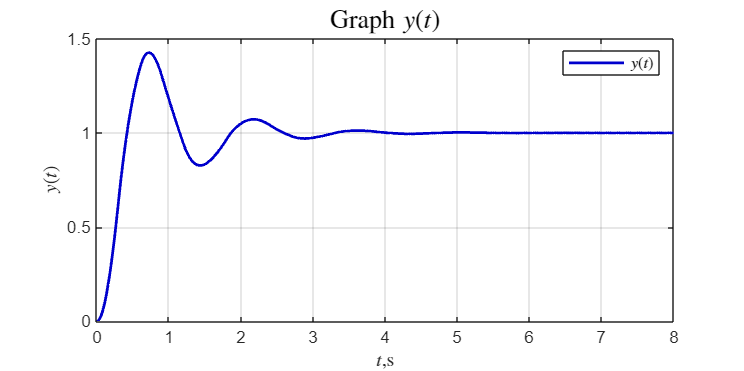


full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_3\Discrete_report_3\pic\' ...
    '1_u.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);


figure('Position', [100 100 800 400]);
plot(t_time, y_data, '-', 'LineWidth', 1.5, 'Color', d_color);

grid on;

title('Graph $y(t)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(t)$','Interpreter', 'latex' );
xlabel('$t$,s', 'Interpreter', 'latex');
legend('$y (t)$','Interpreter', 'latex')
xlim([0, 8])
hold off;


full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_3\Discrete_report_3\pic\' ...
    '1_y.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);